# ISET3d: Assets

Assets describe the collection of objects and lights that are used in a PBRT scene.  For certain PBRT scenes, we have developed methods to read the assets and store them in an ISET3d rendering **recipe. **We  call the recipe **thisR** and the the assets are in the slot,** thisR.assets**.

The assets slot is a Matlab **tree** class.  Trees are a natural way to represent graphics scenes that comprise multiple objects, including objects that have different parts defined by various colors and surface properties.

The tree consists of a cell array of nodes, each with a unique name, and a vector of integers that specifies the identity of the parent node for every node.  The @tree class has many methods that can be invoked for, say, showing the tree, grafting onto the tree, chopping off a branch, and so forth. 

The nodes of the asset tree, like any tree, can be thought of as the tree branches and leaves.  The  **branches** represent transformations that control the position, orientation, and size of the objects.  These transformations are applied to all the objects below the branch. The **leaves** define the shape and material of the object.

There is a large and growing number of actions we can perform on the asset tree to manipulate the size, position, and material properties of the objects.  This a brief tutorial that illustrates a few of the ways to control the objects in an asset tree.  

The software interface is intended to make controlling the objects close to writing simple sentences.  Much of the programming will consist of **set** and **get** commands that apply to the nodes of the tree. These have the form 

or

ISET3d Methods illustrated here include

**Limitation:  **The most important limitation right now is that we are only capable of parsing PBRT scene files that are (a) exported from Cinema4D, or (b) exported from Blender.  This means we have a limited number of scenes that we can control.  We are hoping to remove this limitation in the near future, but that technology is not yet proven.  

We will be creating additional scenes via Cinema4D and Blender in any event.

**See also **

    t_assetsMotion.m, t_materials.m

## A simple scene

This simple scene has about 25 objects.  Some of the assets have long names. The nodes with figure_3m in the name refer to a blue stick figure at 3 meter distance from the camera.  The ones with figure_6m define a yellow stick figure at 6m distance from the camera.  Here is a low resolution rendering of the scene.  

ieInit;
if ~piDockerExists, piDockerConfig; end
thisR = piRecipeDefault('scene name', 'SimpleScene');

Read 1 materials.
Read 1 textures.
***Scene parsed.



% We set a low resolution for speed.
thisR.set('film resolution',[200 150]);
thisR.set('rays per pixel',32);
thisR.set('fov',45);
thisR.set('nbounces',5);

piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt


scene = sceneSet(scene, 'name', 'reference scene');
sceneWindow(scene);
sceneSet(scene, 'render flag', 'hdr');

## The asset tree

The variable **thisR **is the rendering recipe.  It contains a slot for the assets tree.  We have implemented methods for displaying the tree, either in a figure or printed to the command window.

% Simple tree
thisR.assets

ans =   tree with properties:

      Node: {26×1 cell}
    Parent: [26×1 double]


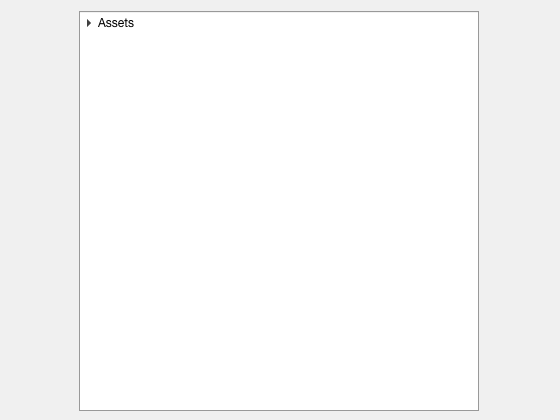


% You can display the asset tree structure in a figure.
thisR.assets.show;


% You can print the asset tree structure in the command window
thisR.assets.print;

                                                                                                         0001ID_root                                                                                                         
                                                  +----------------------------------------------------------++----------------+----------------+----------------+----------------+----------------+----------------+        
                                                  |                                                           |                |                |                |                |                |                |        
                                            0002ID_sky_B                                               0013ID_C..era_B  0014ID_f.._3m_B  0016ID_f.._6m_B  0018ID_S..ere_B  0020ID_g..ass_B  0022ID_m..ror_B  0024ID_P..ane_B 
                                                                                                                

## Example tree methods 

There are many tree methods that can be applied to the assets.  Here are just a few examples.

## How to get an asset

The number of available **recipe** 'get' commands is large and growing.  The get commands related to assets start with the 'node' string.  Here are some examples.

% You can request and asset by its name. 
thisR.get('node','sky_B')

ans = struct with fields:
               type: 'branch'
               name: '0002ID_sky_B'
               size: [1×1 struct]
              scale: {[1 1 1]}
        translation: {[0 0 0]}
           rotation: {[4×3 double]}
    concattransform: []
             motion: []
         transorder: 'TRS'



% The ID will be returned.
thisR.get('node id','sky_B')

ans = 2


% The parent of the asset
thisR.get('node parent','sky_B')

ans = '0001ID_root'


% Use the node number to get the whole struct
thisR.assets.get(2)

ans = struct with fields:
               type: 'branch'
               name: '0002ID_sky_B'
               size: [1×1 struct]
              scale: {[1 1 1]}
        translation: {[0 0 0]}
           rotation: {[4×3 double]}
    concattransform: []
             motion: []
         transorder: 'TRS'



% An asset property 
thisR.get('node','sky_B','translation')

ans = 1×1 cell array
    {[0 0 0]}


thisR.get('node','sky_B','scale')

ans = 1×1 cell array
    {[1 1 1]}


thisR.get('node','001_figure_3m_O','world position')

ans =          0    0.5000  -12.0281


## Rotate the blue man

The point of this implementation is to make it easy to do things like change the position, orientation or other properties of an asset.  Here is the first example.  

% This asset is the leaf of the blue man
nodeName = '001_figure_3m_O'; 

% This places a new branch node representating a rotation just above the
% named leaf asset.  The rotation is (x,y,z) in degrees.  We are rotating
% around the z-axis in this case.
[~,rotateBranch] = thisR.set('node', nodeName, 'rotate', [0, 0, 45]);


## Write and render

piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  11.2 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


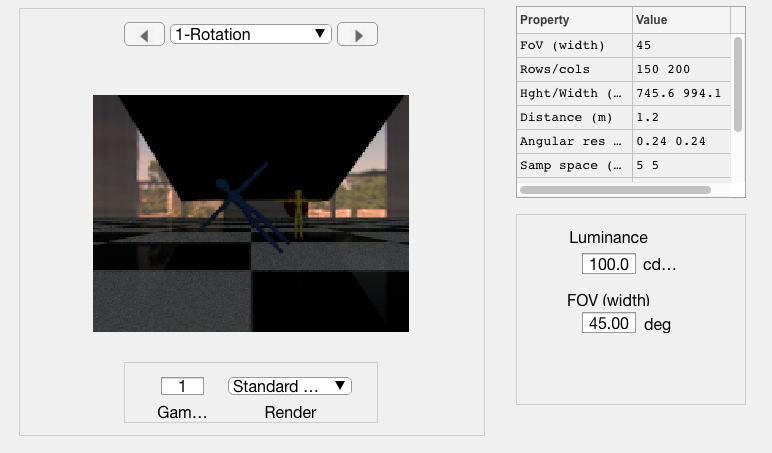

scene = sceneSet(scene, 'name', 'Rotation');
sceneWindow(scene);

**Note**:  the command

will eliminate the rotation branch and return the blue man to upright

## Translate

% This is the object representing the yellow man
nodeName = '001_figure_6m_O';

% In this example, we find the branch node that is just above the yellow
% man, representing its position, rotation and such.
thisNode = thisR.get('node parent id',nodeName);

% We add a translation, moving yellow man 2 meters in the z direction.
[~,translateBranch] = thisR.set('node', thisNode, 'translate', [0, 0, -2]);

% This time the new branch is below the branch, but above the object (leaf)
% that contains the object shape.
thisR.assets.print;

                                                                                                         0001ID_root                                                                                                         
                                                  +----------------------------------------------------------++----------------+----------------+----------------+----------------+----------------+----------------+        
                                                  |                                                           |                |                |                |                |                |                |        
                                            0002ID_sky_B                                               0013ID_C..era_B  0014ID_f.._3m_B  0016ID_f.._6m_B  0018ID_S..ere_B  0020ID_g..ass_B  0022ID_m..ror_B  0024ID_P..ane_B 
                                                                                                                


piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt



scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  10.0 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


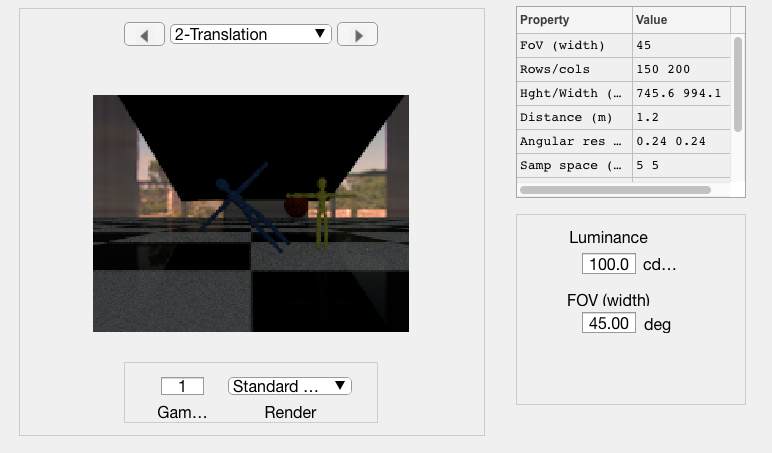

scene = sceneSet(scene, 'name', 'Translation');
sceneWindow(scene);

## Scale

% This is the object representing the yellow man
nodeName = '001_figure_6m_O';

% We scale the size of the yellow man
[~,scaleBranch] = thisR.set('node', nodeName, 'scale', 1.2);

% This time the new branch is below the branch, but above the object (leaf)
% that contains the object shape.
thisR.assets.show;


piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt



scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  10.1 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


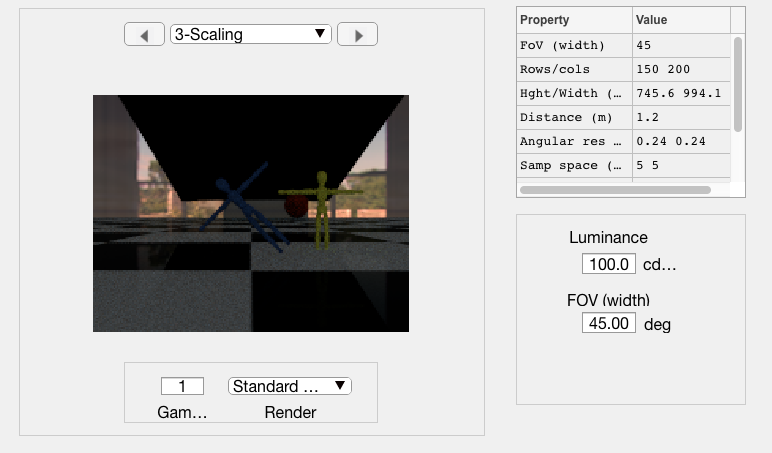

scene = sceneSet(scene, 'name', 'Scaling');
sceneWindow(scene);

## Add an object

% The blue man's transformation node.
nodeName = 'figure_3m_B';

% Get the subtree for the blue man.  We make a copy.
thisSubtree = thisR.get('node',nodeName,'subtree');

% We will add this subtree to the parent of the node.
parent = thisR.get('node parent',nodeName);     % The parent

% To fix
%
% We should try to change the name.
% thisSubtree.Node{1}.name = 'newBlueGuy_B';

Unable to set the 'Node' property of class 'tree' because it is read-only.

% thisSubtree.Node{2}.name = 'newBlueGuy_O';


% This is ugly.  We will fix it some day.
if ischar(parent)
    thisR.set('node','root','graft',thisSubtree);
else
    thisR.set('node',parent.name,'graft',thisSubtree);
end



% We add the asset below the parent of the current blue man. 

% Calls the function to insert an asset below a parent.
thisR.set('node',parent.name,'add',newNode);    

thisR.assets.show;

thisR.set('node',newNode.name,'rotate',[0 0 -45]);
thisR.set('node',newNode.name,'translate',[1 0 0]);
thisR.assets.print;

piWrite(thisR);
scene = piRender(thisR, 'render type', 'radiance');
scene = sceneSet(scene, 'name', 'blueguy2');
sceneWindow(scene);

## Delete an object

thisNode = '001_figure_3m_O'; 
thisR.set('node',thisNode,'delete');
thisR.assets.print;

                                                                                                         0001ID_root                                                                                                         
                                                  +----------------------------------------------------------++----------------+----------------+----------------+----------------+----------------+----------------+        
                                                  |                                                           |                |                |                |                |                |                |        
                                            0002ID_sky_B                                               0013ID_C..era_B  0014ID_f.._3m_B  0015ID_f.._6m_B  0017ID_S..ere_B  0019ID_g..ass_B  0021ID_m..ror_B  0023ID_P..ane_B 
                                                                                                                


piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  11.5 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


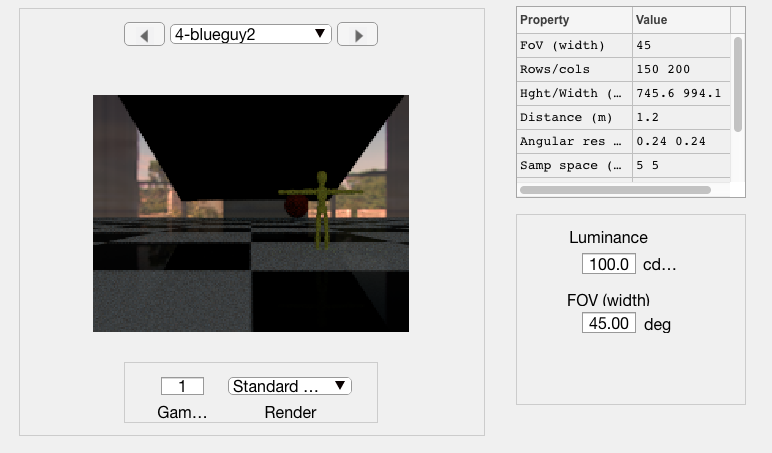

scene = sceneSet(scene, 'name', 'blueguy2');
sceneWindow(scene);

## Delete a translate node

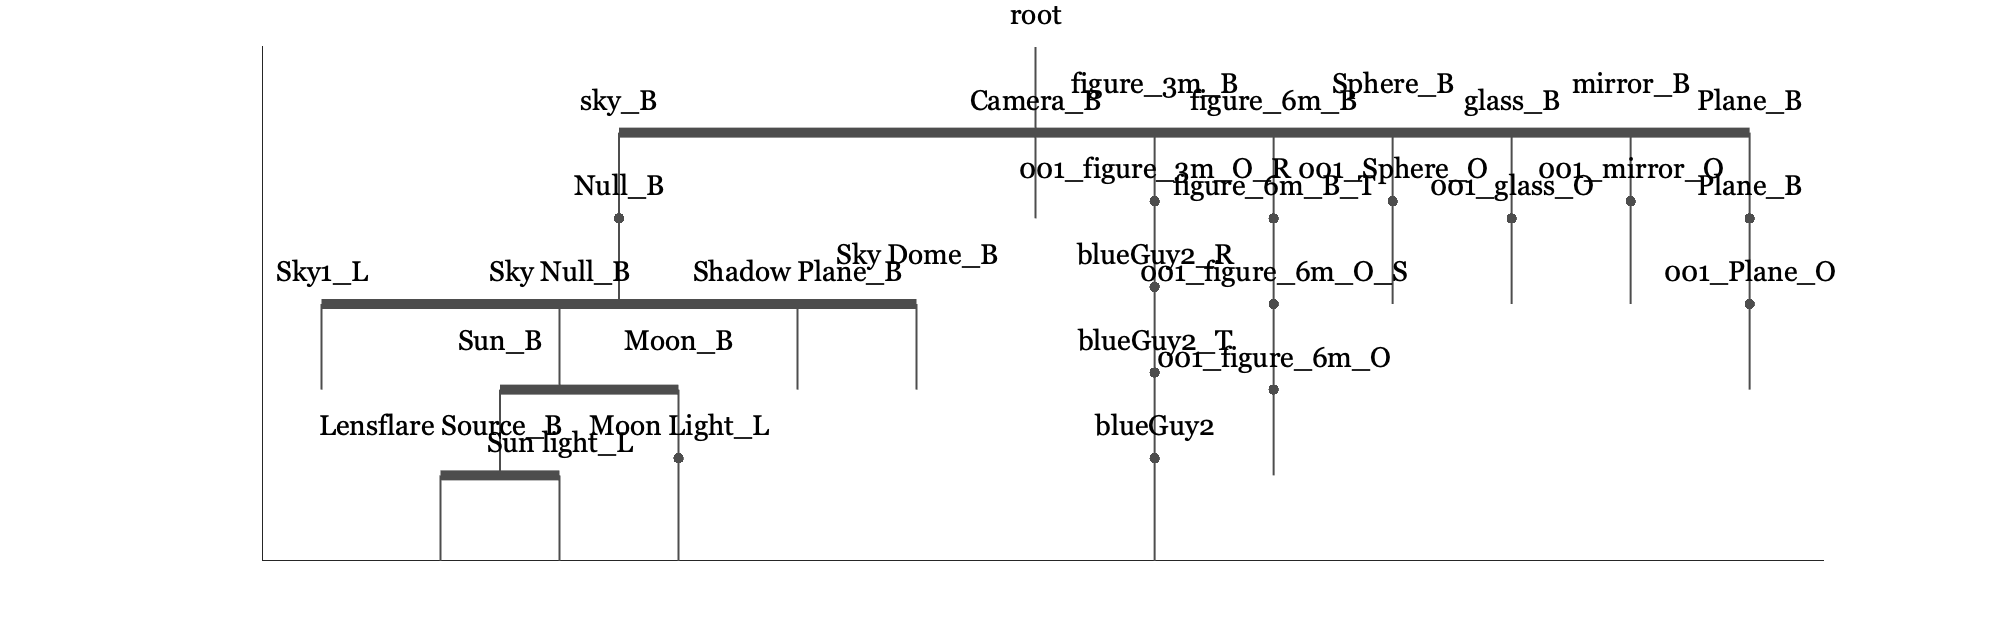

thisR.assets.show;

nodeName = 'blueGuy2'; 
parentID = thisR.get('node parent id',nodeName);
thisR.set('node',parentID,'delete');

piWrite(thisR);

Overwriting PBRT file /Users/zhenyi/git_repo/dev/iset3d/local/SimpleScene/SimpleScene.pbrt


[scene, results] = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/zhenyi/git_repo/dev/iset3d/local/SimpleScene" --volume="/Users/zhenyi/git_repo/dev/iset3d/local/SimpleScene":"/Users/zhenyi/git_repo/dev/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/zhenyi/git_repo/dev/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/zhenyi/git_repo/dev/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  4.1 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


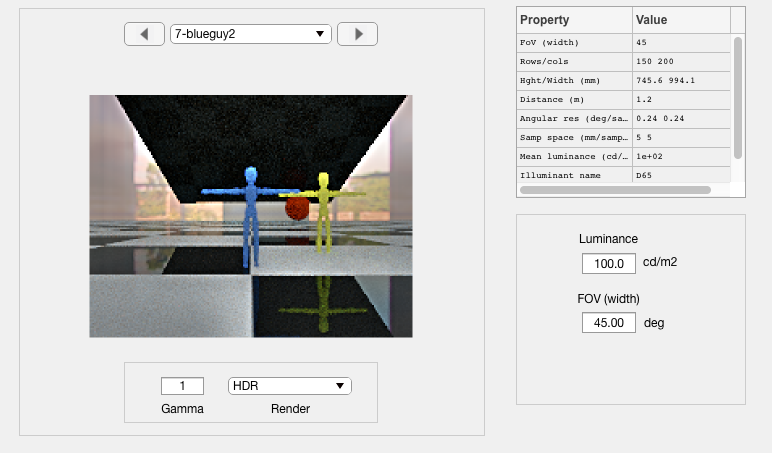

scene = sceneSet(scene, 'name', 'blueguy2');
sceneWindow(scene);